clc
close all
clear all
set(gcf,'Visible','on')

## Partie 1

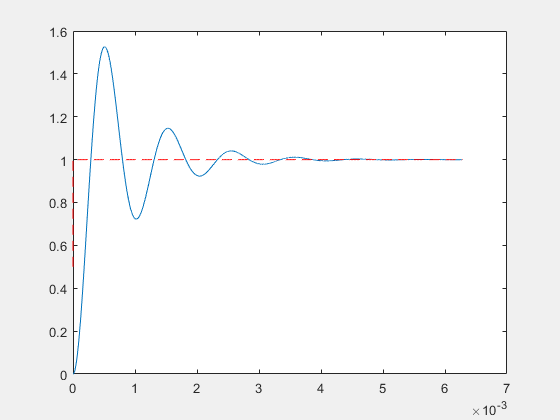

load('Revision bis\reponse_indicielle.mat')
T = reponse_indicielle(:,1);
Y = reponse_indicielle(:,2);

plot(T,Y);
hold on
plot(T,heaviside(T),'--r');


D = max(Y)-Y(end);
k = 1;
y = Y-1;
for i=1:1:length(T)-1
    if(y(i)*y(i+1)<0 && y(i)>0)
        a(k) = T(i);
        k = k+1;
    end
end

Ty = a(2)-a(1);

disp(Ty)

    0.0010



## Partie 2

for j=1:1:length(T)
    if or(Y(j)<Y(end)*0.95,Y(j)>Y(end)*1.05)
        t5 = T(j+1);
    end
end
disp(t5);

    0.0022



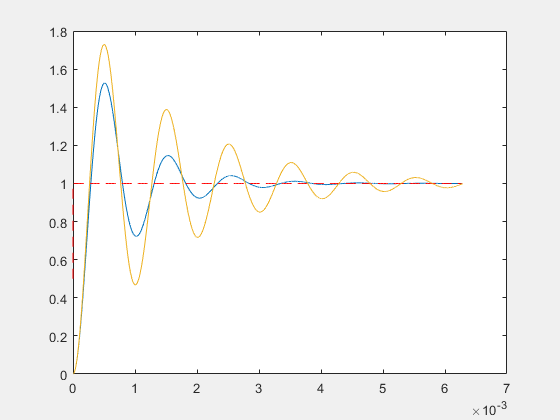

$$\begin{array}{l} {\mathrm{e}}^{-\frac{2\,\pi^{2}}{5}}\,\left(\cosh\left(\sigma_{2}\right)-\frac{\sqrt{99}\,\sinh\left(\sigma_{2}\right)\,\mathrm{i}}{99}\right)-{\mathrm{e}}^{-\frac{320\,\pi^{2}}{9999}}\,\left(\cosh\left(\sigma_{1}\right)-\frac{\sqrt{99}\,\sinh\left(\sigma_{1}\right)\,\mathrm{i}}{99}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{320\,\sqrt{99}\,\pi^{2}\,\mathrm{i}}{9999}\\ \sigma_{2}=\frac{2\,\sqrt{99}\,\pi^{2}\,\mathrm{i}}{5} \end{array}$$

Conversion to logical from sym is not possible.


syms w0 m p t

H = 1./(1+2*m*(p/w0)+(p/w0).^2);

% m = [0.1 0.3 0.6 1.01 1.5 2];
m = 0.1;
w0 = 2*pi*1e3;

h = ilaplace(H/p,p,t);

t = T;

plot(t,subs(h));